clc, close all, clear all;
A = [1 2 1 3; 1 -2 1 2; 2 4 2 1; 5 4 3 1]

A =      1     2     1     3
     1    -2     1     2
     2     4     2     1
     5     4     3     1


B = [2 1; 1 1; 9 2; 0 0]

B =      2     1
     1     1
     9     2
     0     0


C = [1 0 0 0; 0 1 0 0]

C =      1     0     0     0
     0     1     0     0


%D = zeros(2,2)
D = rand(2,2)

D =     0.8147    0.1270
    0.9058    0.9134



%1er paso LQR-I
nx = size(A,1)

nx = 4

ny = size(C,1)

ny = 2

nu = size(B,2)

nu = 2


%LQGI
AOL=[A zeros(nx,ny);-C zeros(ny,ny)]

AOL =      1     2     1     3     0     0
     1    -2     1     2     0     0
     2     4     2     1     0     0
     5     4     3     1     0     0
    -1     0     0     0     0     0
     0    -1     0     0     0     0


BOL=[B;zeros(ny,nu)]

BOL =      2     1
     1     1
     9     2
     0     0
     0     0
     0     0


QOL=diag([100 100 100 100 10000 10000])

QOL =          100           0           0           0           0           0
           0         100           0           0           0           0
           0           0         100           0           0           0
           0           0           0         100           0           0
           0           0           0           0       10000           0
           0           0           0           0           0       10000


ROL=0.001*eye(nu);
KOL=lqr(AOL,BOL,QOL,ROL)

KOL = 1.0e+03 *

    0.5019   -0.3554    0.2469    0.4683    0.7389    3.0747
    0.9977   -0.3073   -0.1164    0.2532   -3.0747    0.7389


K=KOL(:,1:nx)

K =   501.9399 -355.3889  246.8713  468.2796
  997.6994 -307.3399 -116.4184  253.2416


Ki=-KOL(:,(nx+1):end)

Ki = 1.0e+03 *

   -0.7389   -3.0747
    3.0747   -0.7389


Kr=inv(-(C-D*K)*((A-B*K)^-1*B)+D)

Kr = 1.0e+03 *

    0.1907   -0.1911
    1.1104   -0.0197



Gw=eye(nx);
Qw=0.1*eye(nx);
Vv=0.0001*eye(ny);
L=lqe(A,Gw,C,Qw,Vv)

L =    39.4327    6.4806
    6.4806   33.5261
   66.0301   57.1984
   60.0149   43.1857



ACL=[A -B*K B*Ki;
    L*C A-B*K-L*C B*Ki;
    -C D*K -D*Ki];
BCL=[B*Kr;B*Kr;eye(ny)-D*Kr];
CCL=[C -D*K D*Ki]

CCL = 1.0e+03 *

    0.0010         0         0         0   -0.5356    0.3286   -0.1863   -0.4137   -0.2116   -2.5989
         0    0.0010         0         0   -1.3659    0.6026   -0.1173   -0.6555    2.1391   -3.4600


4 states removed.


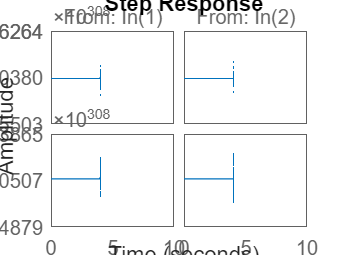

DCL=D*Kr;
GCL=ss(ACL,BCL,CCL,DCL);
step(minreal(GCL),10)